# 03. Cds 센서를 사용하여 플래쉬를 켜놓은 핸드폰과의 거리 변화에 따른 저항값의 변화를 읽어 그래프로 나타내고 분석하시오.

# 1. Data Load

data = importdata('Assignment0304_이형섭_201901766.txt')  

data =    133    85
   131    84
   133    83
   137    83
   134    83
   132    82
   137    82
   139    83
   136    81
   136    82


# 2. CdS Sensor 값만 추출

data_cds = data(:,1) % 밝기에 따른 ADC값

data_cds =    133
   131
   133
   137
   134
   132
   137
   139
   136
   136



% V2 : analogRead 함수를 통해 얻어진 ADC만 추출
V2 = data_cds

V2 =    133
   131
   133
   137
   134
   132
   137
   139
   136
   136



% V2 : analogRead값(0~1023, 10-bit resolution)을 0~5V 범위로 변환
V2 = V2 .* (5/1023)

V2 =     0.6500
    0.6403
    0.6500
    0.6696
    0.6549
    0.6452
    0.6696
    0.6794
    0.6647
    0.6647



% V2, R2의 정보로 R1 구하기
% V2 = (R2/(R1+R2)) * 5
R2 = 10000

R2 = 10000

R1 = (5*R2)./V2 - R2

R1 = 1.0e+04 *

    6.6917
    6.8092
    6.6917
    6.4672
    6.6343
    6.7500
    6.4672
    6.3597
    6.5221
    6.5221


# 3. Ultra Sonic Sensor 값만 추출

data_cm = data(:,2) % cm값만 추출

data_cm =     85
    84
    83
    83
    83
    82
    82
    83
    81
    82


# 4. Graph 그리기(플래쉬 거리에 따른 저항값의 변화)

x = data_cm

x =     85
    84
    83
    83
    83
    82
    82
    83
    81
    82


y = R1 ./ 1000 % y축 단위를 K[ohm]으로 하기 위해 K로 나눠준다.

y =    66.9173
   68.0916
   66.9173
   64.6715
   66.3433
   67.5000
   64.6715
   63.5971
   65.2206
   65.2206


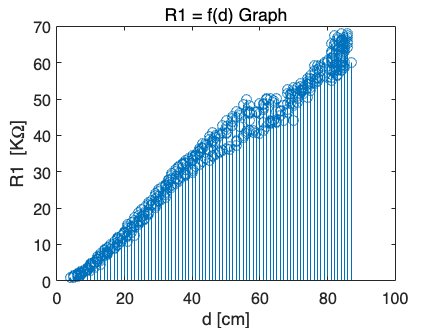


stem(x, y); % 이산적인 값을 찍어봄으로써 해당 d에 대한 R1의 분포를 통해 상관관계를 파악하기 위함
xlabel('d [cm]');       
ylabel('R1 [K\Omega]');       
title('R1 = f(d) Graph');  